clear;clc;close all;
showing_performance=0

showing_performance = 0

startover=1

startover = 1

epoch: 1, 7112 errors, total duration: 3.7514, state saved
epoch: 2, 3143 errors, total duration: 11.0991, state saved
epoch: 3, 2423 errors, total duration: 17.5729, state saved
epoch: 4, 2019 errors, total duration: 24.0683, state saved
epoch: 5, 1720 errors, total duration: 30.5048, state saved
epoch: 6, 1517 errors, total duration: 36.9565, state saved
epoch: 7, 1324 errors, total duration: 43.3645, state saved
epoch: 8, 1227 errors, total duration: 49.7865, state saved
epoch: 9, 1119 errors, total duration: 56.2308, state saved
epoch: 10, 1061 errors, total duration: 62.6485, state saved
epoch: 11, 948 errors, total duration: 69.1113, state saved
epoch: 12, 902 errors, total duration: 75.5641, state saved
epoch: 13, 839 errors, total duration: 81.9941, state saved
epoch: 14, 795 errors, total duration: 88.44, state saved
epoch: 15, 745 errors, total duration: 94.8551, state saved
epoch: 16, 696 errors, total duration: 101.298, state saved
epoch: 17, 668 errors, total duration: 107

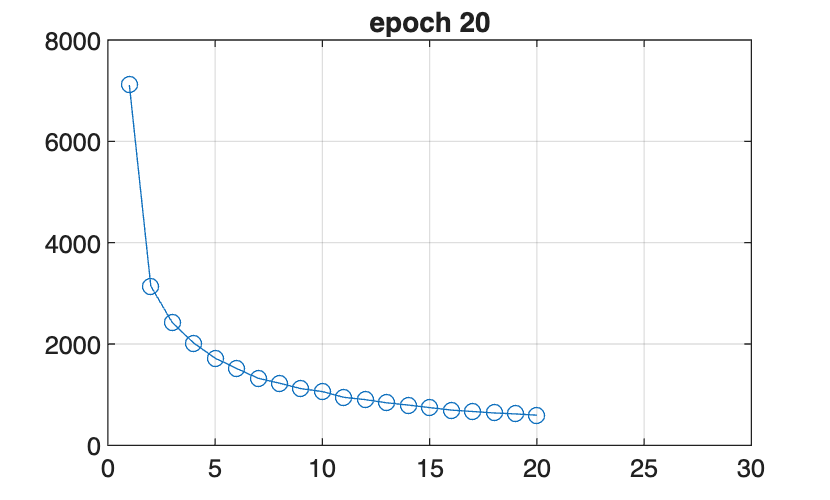

%You get to continue training from last training in case you want to
%Enter C to continue from last save point, or A if you want to start anew
if ~startover
    %loads all variables from last session
    load('state.mat');
    continuing = true;  %so we know not to generate a new random network
    i=1;    %or else it will be 60000
    disp(['Continuing from epoch ' num2str(epoch) ' example ' num2str(i)]);
    %plot learning error history for all epochs so far
    figure(1);plot(errors_list,'-o'); xlim([0,N_epochs]);ylim([0,60000]);grid on;
    pause(1)    %gives the time for the figure to display
else
    continuing = false;
end

%start timing
tic
if ~continuing
    total_duration = 0;
    %model:
    input_layer_units = 28*28;
    hidden_layer_units = 100;    %you can play around setting this
    %too many hidden layer units will overlearn
    %(100 might be too much already)
    output_layer_units = 10;
    W1 = rand(hidden_layer_units,input_layer_units)*2 - 1;
    b1 = rand(hidden_layer_units,1)*2 - 1;
    W2 = rand(output_layer_units,hidden_layer_units)*2 - 1;
    b2 = rand(output_layer_units,1)*2 - 1;
    %There are 3 possible activation functions: purelin, sigmoid, and ReLU 
    %only the sigmoid/sigmoid combination gives any good result, not sure 
    %if that's how it's normal
    layers = {'sigmoid','sigmoid'};

    %data
    load train-images-idx3-ubyte.mat
    load train-labels.idx1-ubyte.mat
    %input images are flattened as 60000 columns of 784 values
    X = reshape(pixel,28*28,1,size(pixel,3)); clear pixel;
    X = reshape(X,28*28,size(X,3));
    %normalize input to [0,1]
    X = X/255;
    %target vectors are one-hot encoded
    T = zeros(10,length(label));
    for i = 1:size(label,2)
        T(label(i)+1,i) = 1;
    end
    %discard voluminous unneeded variables
    clear label;

    i=1;
    epoch = 1;
    errors = 0;
    %N_epochs should be sufficient (probably above 90% good recognition)
    N_epochs = 30;
    %this is to plot learning error history
    %(number of errors for each epoch)
    errors_list = 0;
    %randomize order of presentation of examples
    example_list = randperm(length(X));
end
%I like to hear a small beep sound when each epoch is complete:
y = sin(2*pi*880*(0:1/16000:0.1));
while epoch <= N_epochs
    %forward:
    [O,Y] = forward(X(:,example_list(i)),W2,b2,W1,b1,layers);

    %get network answer for this input
    [whatever,answer] = max(O); 
    answer = answer - 1;
    %get correct answer from T matrix:
    [whatever,correct_answer] = max(T(:,example_list(i)));
    correct_answer = correct_answer - 1;
    %compare results
    if answer ~= correct_answer
        errors = errors+1;
    end

    E = (T(:,example_list(i))-O).^2;
    %backward:
    
    if strcmp(layers{2},'ReLU')
        delta2 = 2*(O-T(:,example_list(i))).*heaviside(O);
    elseif strcmp(layers{2},'sigmoid')
        delta2 = 2*(O-T(:,example_list(i))).*O.*(1-O);
    elseif strcmp(layers{2},'purelin')
        delta2 = 2*(O-T(:,example_list(i)));
    else
        error(['unknown layer type: ' layers{2}])
    end
    
    %do the same thing for first layer
  
    if strcmp(layers{1},'ReLU')
        delta1 = W2'*delta2.*heaviside(Y); %using ReLU
    elseif strcmp(layers{1},'sigmoid')
        delta1 = W2'*delta2.*(Y.*(1-Y));    %using sigmoid
    elseif strcmp(layers{1},'purelin')
        delta1 = W2'*delta2;    %using purelin
    else
        error(['unknown layer type: ' layers{2}])
    end
    
    %complete computation of gradients
    deltaW2 = delta2*Y';
    deltab2 = delta2;
    deltaW1 = delta1*(X(:,example_list(i)))';
    deltab1 = delta1;
    %update weights (learning rate arbitrarily set to 0.1, best value I've found)
    W2 = W2 - 0.1*deltaW2;
    b2 = b2 - 0.1*deltab2;
    W1 = W1 - 0.1*deltaW1;
    b1 = b1 - 0.1*deltab1;

    i = i+1;
    if i==length(T)
        %end of epoch
        total_duration = total_duration + toc;  %update duration
        tic
        save('state.mat');  %save data
        %it's not a good idea to save too often, slows down the
        %calculations a lot. I've found that saving every epoch was a good
        %compromise
        disp(['epoch: ' num2str(epoch) ', ' num2str(errors) ' errors, total duration: ' num2str(total_duration) ', state saved']);
        i=1;
        %add number of errors to learning errors history
        errors_list(epoch) = errors;
        if errors == min(errors_list)
            %remember best parameters so far
            finalW2 = W2;
            finalb2 = b2;
            finalW1 = W1;
            finalb1 = b1;
        end
        %This plots the learning error history
        figure(1);plot(errors_list,'-o');xlim([0,N_epochs]);grid on;
        title(['epoch ' num2str(epoch)])
        %if you don't pause the system to let the figure appear, it will
        %appear much later than it should:
        pause(1)
        epoch = epoch + 1;
        %play beep sound
        
        %if recognition rate for this epoch is higher than 99%, stop
        %training. I set this to arbitrarily high values.
        %If the network's gonna learn in just 10 epochs, what's the point
        %of doing 100 epochs?
        if errors/size(X,2) < 0.01
            break;
            %sound to let you know the network has learned
           
        end
        %reset errors counter and generate new example list
        errors = 0;
        example_list = randperm(length(X));
    end
end


disp(['errors:' num2str(min(errors_list))])

errors:595



if epoch < N_epochs
    %if the system has learned before we've done the chosen number of
    %epochs, let the user know
    disp(['The model has learned after only ' num2str(epoch) ' epochs'])
end

The model has learned after only 21 epochs


disp('Done training! Now testing network performance')

Done training! Now testing network performance


%test:
%This lets the user see each example image and the network's answer to this
%example
%If you just want to know the validation rate, say N
%If you want to see the network's reponse to each input, say Y

disp('Testing...')

Testing...


%load test data (same as for training)
load t10k_images_idx3_ubyte.mat
load t10k-labels.idx1-ubyte.mat
images = pixel; %I prefer this to be named "images" and not "pixel"
X = reshape(pixel,28*28,1,size(pixel,3)); clear pixel;
X = reshape(X,28*28,size(X,3));
X = X/255;
T = zeros(10,length(label));
for i = 1:size(label,2)
    T(label(i)+1,i) = 1;
end
clear label;
errors = 0;
%things are pretty straightforward from here, we're just counting the
%errors
for i = 1:length(X)
    O = forward(X(:,i),finalW2,finalb2,finalW1,finalb1,layers);
    [osf,answer] = max(O); answer = answer -1;
    [osf,correct_answer] = max(T(:,i));
    correct_answer = correct_answer - 1;
    if answer ~= correct_answer
        errors = errors + 1;
    end
    if showing_performance == 1
        figure(2)
        imshow(images(:,:,i)); 
        title(['Answer given by network: ' num2str(answer)])
        A = input('keep showing performances? (Y/N)','s');
        if strcmpi(A,'N')
            showing_performance = 0;
        end
    end
end

%display the results to the user:
disp(['Errors on test set: ' num2str(errors) '/' num2str(length(X))]);

Errors on test set: 290/10000


disp(['Error rate on test set: ' num2str(errors*100/length(X)) '%']);

Error rate on test set: 2.9%



%You can use the next line to save the model:
%save('saved_model.mat','finalW2','finalW1','finalb2','finalb1','layers');

% Extract values from all layers
output=zeros(length(X),10);
hiddenlayer=zeros(length(X),100);
correct_answer=zeros(length(X),1);
answer=zeros(length(X));
for i = 1:length(X)
    [output(i,:), hiddenlayer(i,:)] = forward(X(:,i),finalW2,finalb2,finalW1,finalb1,layers);
    [osf,answer(i)] = max(output(i,:)); answer(i) = answer(i) -1;
    [osf,correct_answer(i)] = max(T(:,i));
    correct_answer(i) = correct_answer(i) - 1;
end

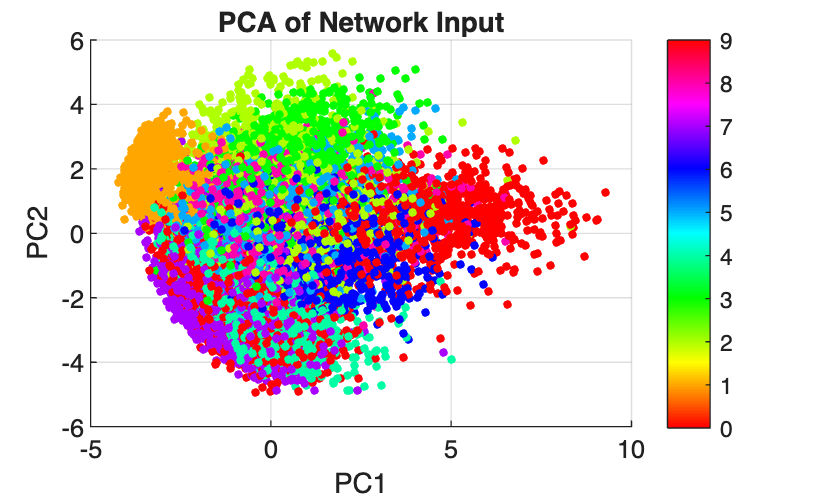


[coeff,score,latent] =pca(X');
figure;
hold on
colormap("hsv")
scatter(score(:,1),score(:,2),10,vec2ind(T)-1,'filled');
xlabel('PC1'); ylabel('PC2');
title('PCA of Network Input'); colorbar; grid on;
hold off

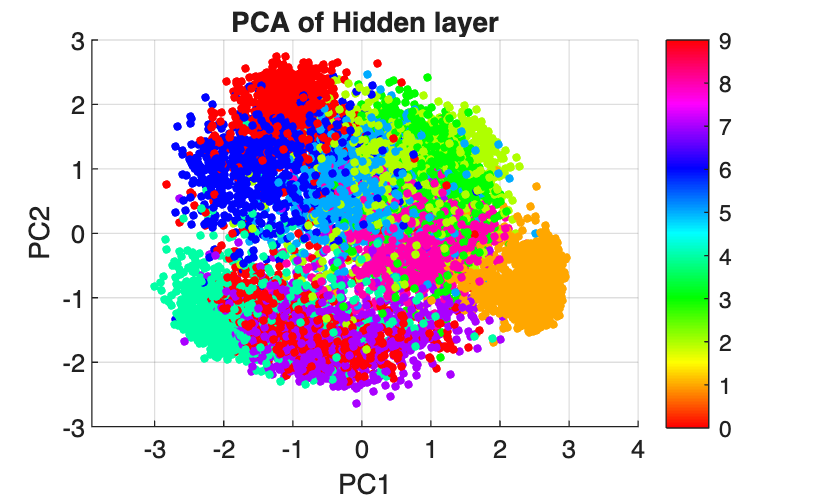




[coeff,score,latent] =pca(hiddenlayer);
figure;
hold on
colormap("hsv")
scatter(score(:,1),score(:,2),10,vec2ind(T)-1,'filled');
xlabel('PC1'); ylabel('PC2');
title('PCA of Hidden layer'); colorbar; grid on;
hold off

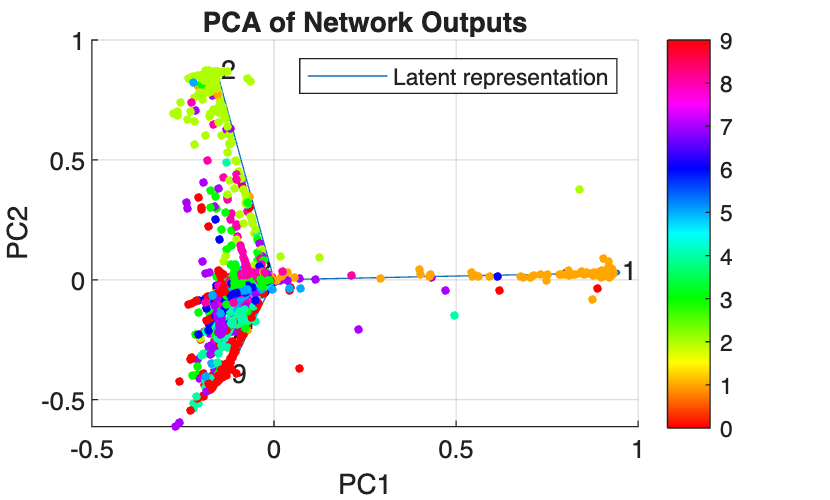




[coeff,score,latent] =pca(output);
figure;
hold on
colormap("hsv")
l=string(0:9);

biplot(coeff(:,1:2), "VarLabels",l);
scatter(score(:,1),score(:,2),10,vec2ind(T)-1,'filled');
xlabel('PC1'); ylabel('PC2');
legend("Latent representation")
title('PCA of Network Outputs'); colorbar; grid on;
hold off

selidx=find(correct_answer<=2)

selidx =      2
     3
     4
     6
    11
    14
    15
    26
    29
    30
    32
    36
    38
    39
    40


%% LLE
neighbors=20

neighbors = 20

dim=6

dim = 6

Xlle=lle(X(:,selidx), neighbors, dim);

LLE running on 10000 points in 784 dimensions
-->Finding 20 nearest neighbours.
-->Solving for reconstruction weights.
-->Computing embedding.


Done.


Hlle=lle(hiddenlayer(selidx,:)', neighbors, dim);

LLE running on 10000 points in 100 dimensions
-->Finding 20 nearest neighbours.
-->Solving for reconstruction weights.
-->Computing embedding.


Done.


Olle=lle(output(selidx,:)', neighbors, dim);

LLE running on 10000 points in 10 dimensions
-->Finding 20 nearest neighbours.
-->Solving for reconstruction weights.
   [note: K>D; regularization will be used]
-->Computing embedding.


Done.


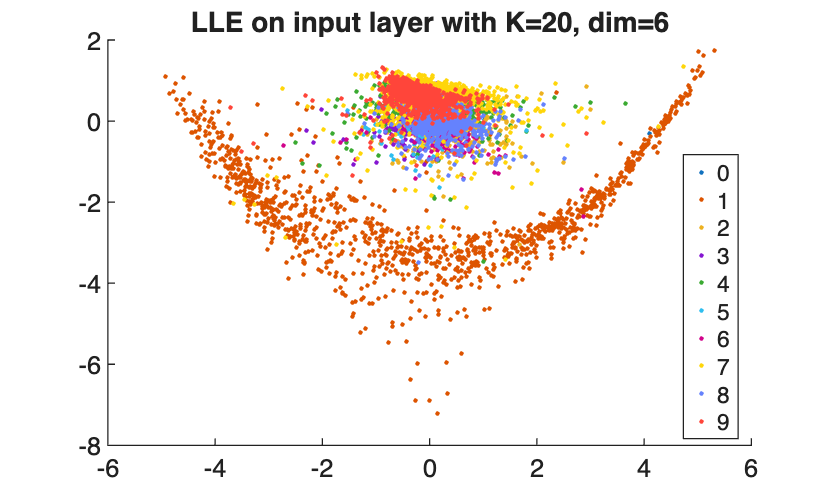

figure;
gscatter(Xlle(1,1:end), Xlle(2,1:end), correct_answer(selidx))
title("LLE on input layer with K="+num2str(neighbors)+", dim="+num2str(dim))

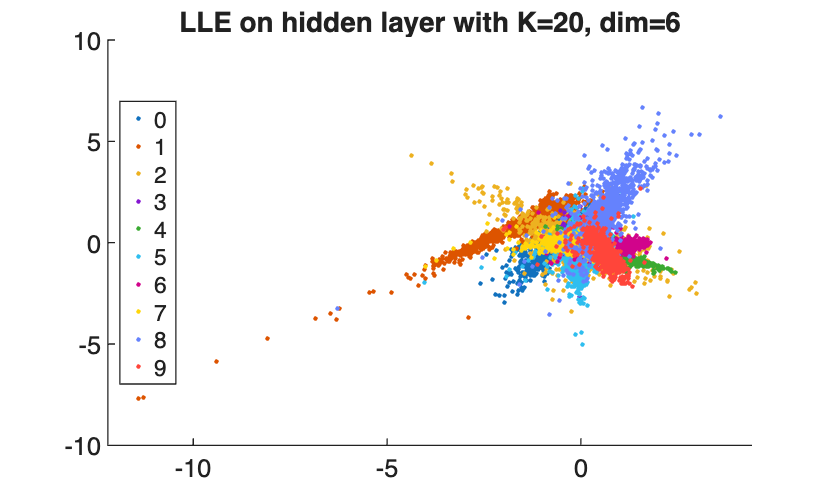

figure;
gscatter(Hlle(1,1:end), Hlle(2,1:end), correct_answer(selidx))
title("LLE on hidden layer with K="+num2str(neighbors)+", dim="+num2str(dim))

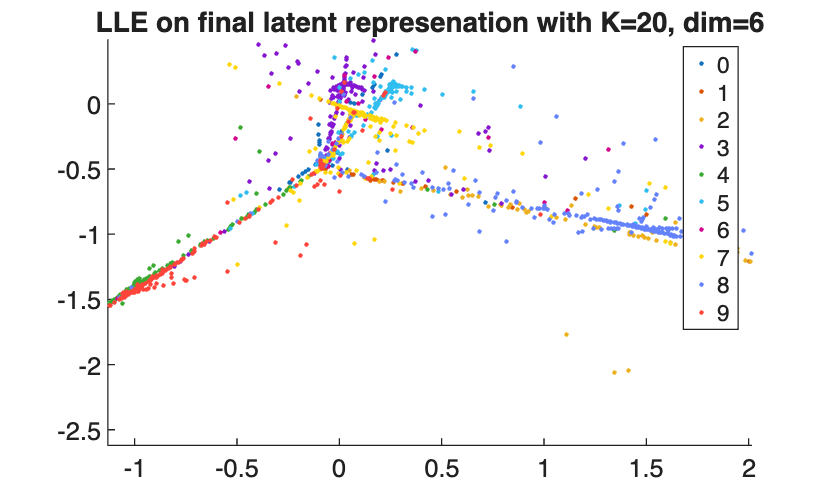

figure;
gscatter(Olle(3,:), Olle(2,:), correct_answer(selidx))
title("LLE on final latent represenation with K="+num2str(neighbors)+", dim="+num2str(dim));

%UMAP

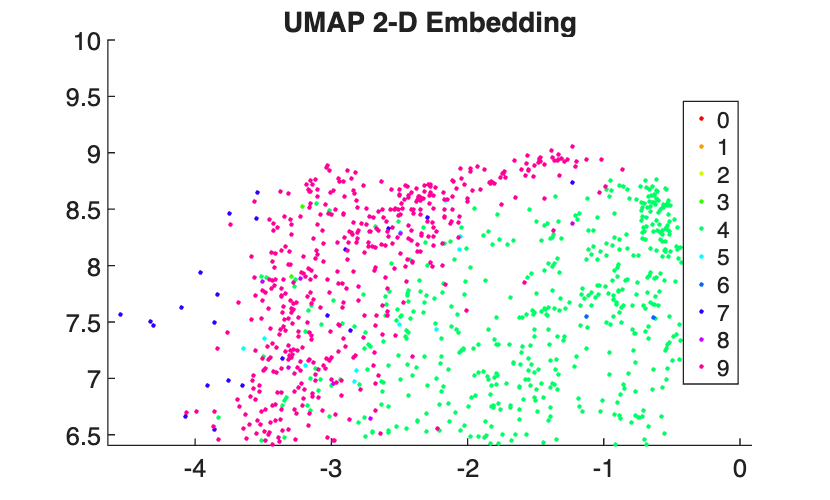

Y2 = umap(X');   % Default number of embedding dimensions is 2
figure;
gscatter(Y2(:,1),Y2(:,2),correct_answer,hsv(10))
title("UMAP 2-D Embedding")

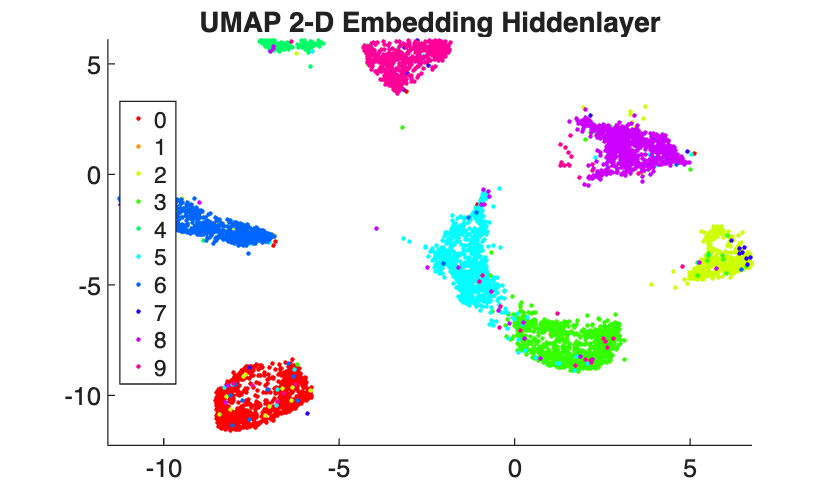

figure;
Y2 = umap(hiddenlayer);   % Default number of embedding dimensions is 2
figure;
gscatter(Y2(:,1),Y2(:,2),correct_answer,hsv(10))
title("UMAP 2-D Embedding Hiddenlayer")

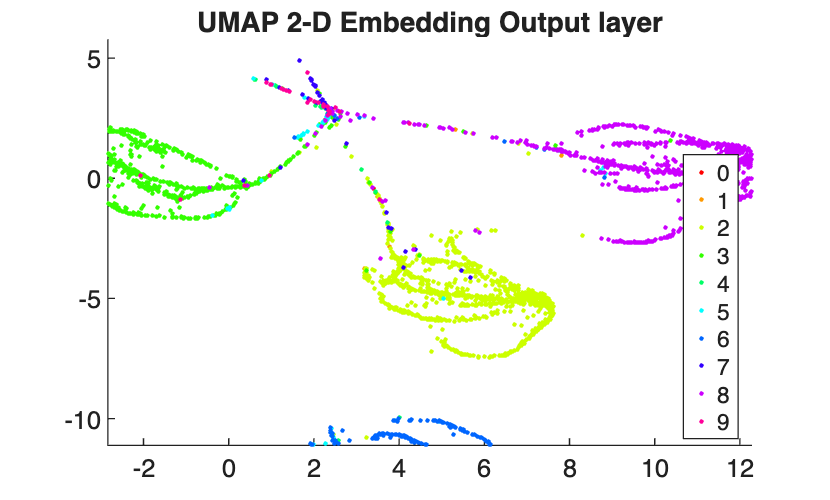

figure;
Y2 = umap(output);   % Default number of embedding dimensions is 2
figure;
gscatter(Y2(:,1),Y2(:,2),correct_answer,hsv(10))
title("UMAP 2-D Embedding Output layer")

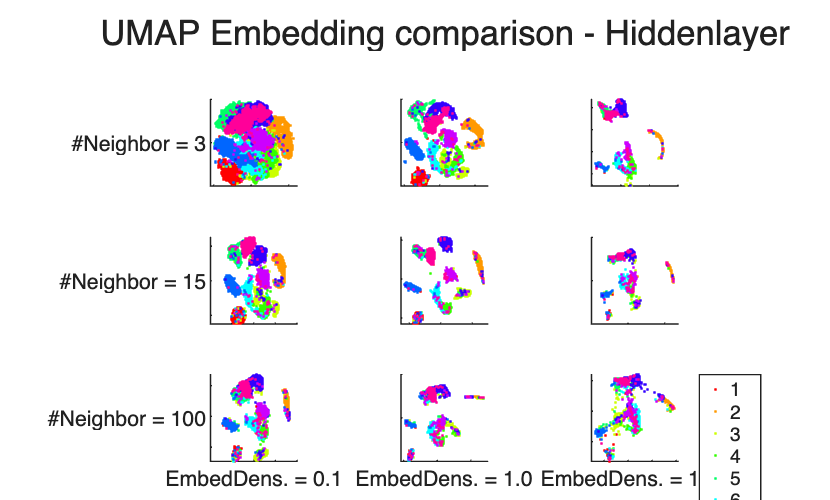

figure;
t = tiledlayout(3,3,TileSpacing="compact",Padding= "compact");

density = [0.1 1 10 0.1 1 10 0.1 1 10];
nNeighbors = [3 3 3 15 15 15 100 100 100];
for i = 1:9
    rng(0,"twister"); % For fair comparison
    E2 = umap(hiddenlayer,Standardize=true,EmbeddingDensity=density(i), ...
        NumNeighbors=nNeighbors(i),Reproducible=true);

    ax = nexttile;
    gscatter(E2(:,1),E2(:,2),correct_answer',hsv(10), ".",3,"off")
    ax.XTickLabel = [];
    ax.YTickLabel = [];
    if i > 6
        xlabel(sprintf("EmbedDens. = %.1f",density(i)),FontSize=8);
    end
    if (mod(i-1,3) == 0)
        ylabel(sprintf("#Neighbor = %d",nNeighbors(i)), ...
            FontSize=8,Rotation=0); 
    end
    axis square
end
legend(string(1:10), "Location","bestoutside")
title(t,"UMAP Embedding comparison - Hiddenlayer")

%SOM
somdim=[4,4]

somdim =      4     4


xsom=selforgmap(somdim)


xsom =

    Neural Network
 
              name: 'Self-Organizing Map'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 0
        sampleTime: 1
 
    connections:
 
       biasConnect: false
      inputConnect:

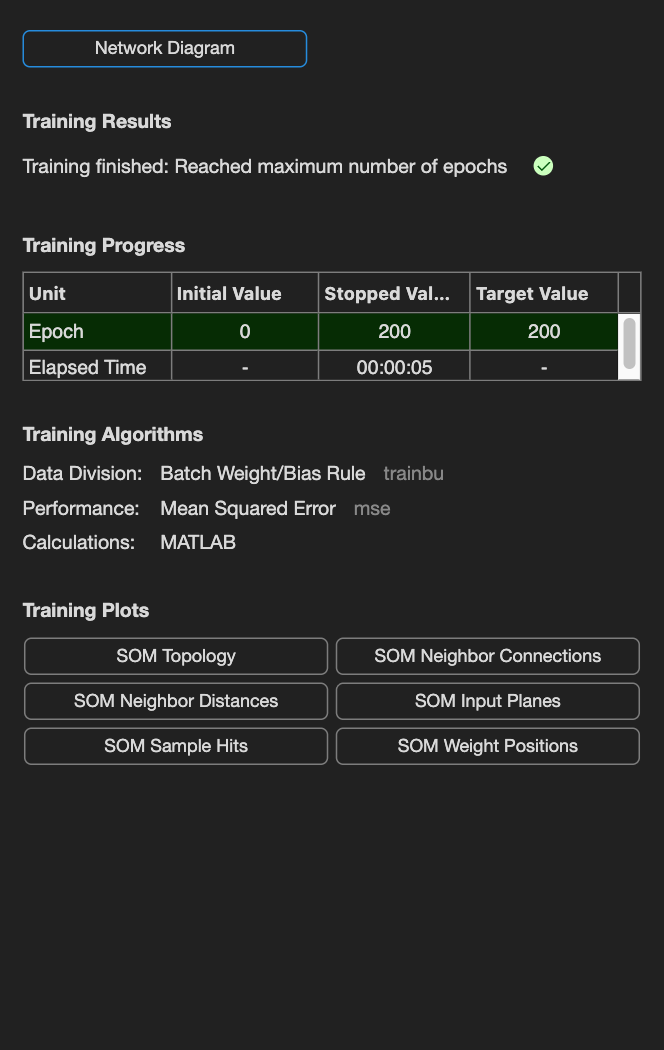


xsom =

    Neural Network
 
              name: 'Self-Organizing Map'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 12544
        sampleTime: 1
 
    connections:
 
       biasConnect: false
      <a href="matlab:doc nnproperty.net_inputConnect">inputConnect<

xsom=train(xsom, X(:,selidx))

hsom=selforgmap(somdim,2500)


hsom =

    Neural Network
 
              name: 'Self-Organizing Map'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 0
        sampleTime: 1
 
    connections:
 
       biasConnect: false
      inputConnect:

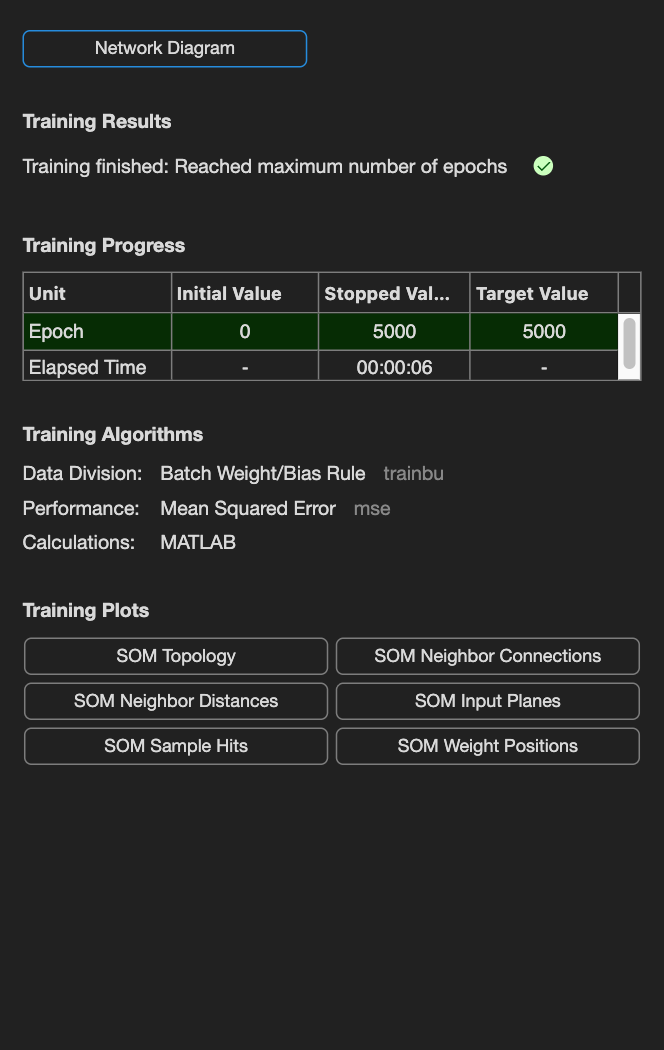


hsom =

    Neural Network
 
              name: 'Self-Organizing Map'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 400
        sampleTime: 1
 
    connections:
 
       biasConnect: false
      <a href="matlab:doc nnproperty.net_inputConnect">inputConnect</a

hsom=train(hsom, hiddenlayer(selidx,:)')

osom=selforgmap(somdim)


osom =

    Neural Network
 
              name: 'Self-Organizing Map'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 0
        sampleTime: 1
 
    connections:
 
       biasConnect: false
      inputConnect:

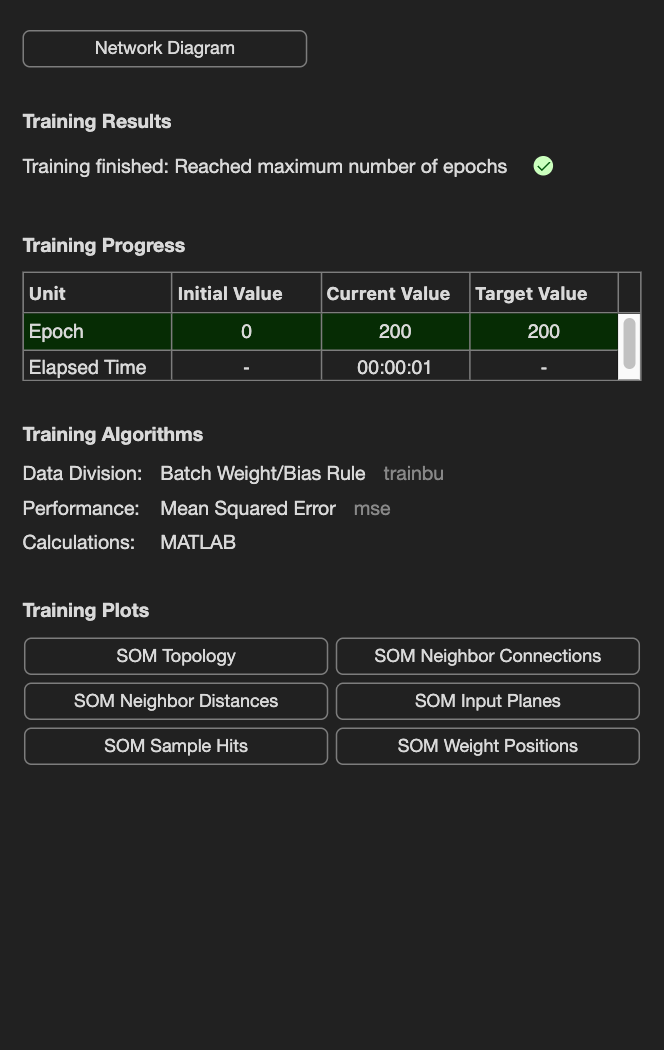

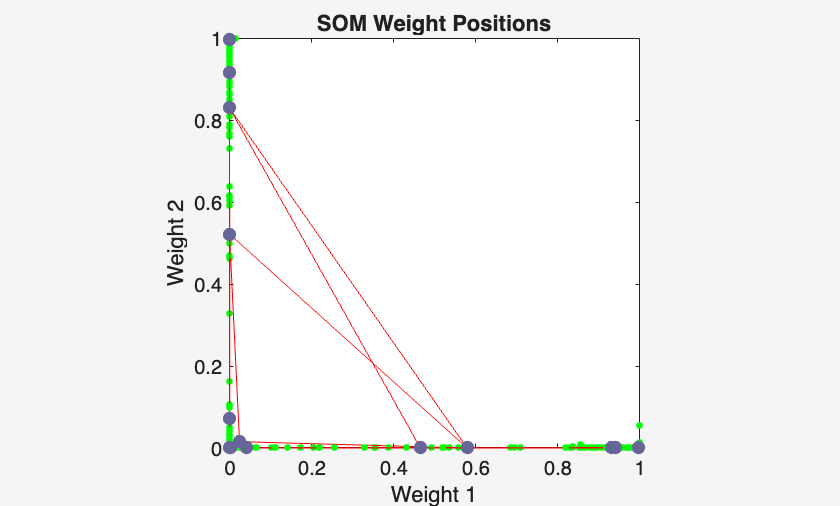


osom =

    Neural Network
 
              name: 'Self-Organizing Map'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 160
        sampleTime: 1
 
    connections:
 
       biasConnect: false
      <a href="matlab:doc nnproperty.net_inputConnect">inputConnect</a

osom=train(osom, output(selidx,:)')